# MINI-PROJECT 1: 

# PERFORMANCE EVALUATION OF POINT-TO-POINT LINKS SUPPORTING PACKET SERVICES

Pedro Caio e Miguel Ferreira

24/10/2024

clearvars; close all; clc

## Task 3

Consider the event driven simulators `Sim3` and `Sim4` developed in **Task 7** of the Practical Guide. In all experiments of this task, consider the cases of $\lambda = 1500 \text{ pps}$, $C = 10 \text{ Mbps}$, $f = 10.000 \text{ Bytes}$ and $n = 10, \ 20, \ 30$ and $40$ VoIP flows. All simulation results should be based on $20$ runs  of the simulator with a stopping criterion of $P = 100.000$ on each run to compute the estimated  values and the $90 \%$ confidence intervals. 

### 3.a. (Evaluation weight: 10%)

Use `Sim3` to estimate the average packet delay and average packet loss of each service (data and VoIP). Recall that in `Sim3`, both services are  statistically multiplexed in a single FIFO queue. Present each of the four performance  parameters in a bar chart with the confidence intervals in error bars. Justify the differences in the performance values obtained for each service and draw all relevant conclusions. 

**Answer:**

% Input parameters
lambda = 1500;                             % pps   (packets/sec)
C = 10;                                     % Mbps  (link bandwidth)
f = 1e4;                                    % Queue size (Bytes)
P = 1e5;                                    % number of packets (stopping criterium)
n_VoIP = [10, 20, 30, 40];                  % number of VoIP flows

% Performance parameters
nrun = 20;                                  % number of runs
nsim = length(n_VoIP);
% data packets
PLdata_3a = zeros(nrun, nsim);
APDdata_3a = zeros(nrun, nsim);
MPDdata_3a = zeros(nrun, nsim);
TT_3a = zeros(nrun, nsim);
% VoIP packets
PLVoIP_3a = zeros(nrun, nsim);
APDVoIP_3a = zeros(nrun, nsim);
MPDVoIP_3a = zeros(nrun, nsim);

for i=1:nsim
    for j=1:nrun
        [PLdata_3a(j,i) , APDdata_3a(j,i) , MPDdata_3a(j,i), TT_3a(j,i), PLVoIP_3a(j,i) , APDVoIP_3a(j,i) , MPDVoIP_3a(j,i)] = Sim3(lambda, C, f, P, n_VoIP(i));
    end
end

With the results the confidence intervals can be computed

alpha = 0.1; % 90% confidence interval
% data packets
PLdata_mean_3a = zeros(1, nsim);
PLdata_moe_3a = zeros(1, nsim);
APDdata_mean_3a = zeros(1, nsim);
APDdata_moe_3a = zeros(1, nsim);
MPDdata_mean_3a = zeros(1, nsim);
MPDdata_moe_3a = zeros(1, nsim);
TT_mean_3a = zeros(1, nsim);
TT_moe_3a = zeros(1, nsim);
% VoIP packets
PLVoIP_mean_3a = zeros(1, nsim);
PLVoIP_moe_3a = zeros(1, nsim);
APDVoIP_mean_3a = zeros(1, nsim);
APDVoIP_moe_3a = zeros(1, nsim);
MPDVoIP_mean_3a = zeros(1, nsim);
MPDVoIP_moe_3a = zeros(1, nsim);

for i = 1:nsim
    [PLdata_mean_3a(i), PLdata_moe_3a(i)] = CI(PLdata_3a(:, i), "PLdata", alpha, nrun);
    [APDdata_mean_3a(i), APDdata_moe_3a(i)] = CI(APDdata_3a(:, i), "APDdata", alpha, nrun);
    [MPDdata_mean_3a(i), MPDdata_moe_3a(i)] = CI(MPDdata_3a(:, i), "MPDdata", alpha, nrun);
    [TT_mean_3a(i), TT_moe_3a(i)] = CI(TT_3a(:, i), "TT", alpha, nrun);

    [PLVoIP_mean_3a(i), PLVoIP_moe_3a(i)] = CI(PLVoIP_3a(:, i), "PLVoIP", alpha, nrun);
    [APDVoIP_mean_3a(i), APDVoIP_moe_3a(i)] = CI(APDVoIP_3a(:, i), "APDVoIP", alpha, nrun);
    [MPDVoIP_mean_3a(i), MPDVoIP_moe_3a(i)] = CI(MPDVoIP_3a(:, i), "MPDVoIP", alpha, nrun);
end

PLdata = 2.34e-01 +- 1.26e-02


APDdata = 2.02e+00 +- 1.38e-02


MPDdata = 9.03e+00 +- 3.01e-02


TT = 7.89e+00 +- 1.32e-02


PLVoIP = 2.66e-02 +- 3.85e-03


APDVoIP = 1.61e+00 +- 1.20e-02


MPDVoIP = 8.68e+00 +- 5.83e-02


PLdata = 4.32e-01 +- 1.97e-02


APDdata = 2.32e+00 +- 1.70e-02


MPDdata = 9.04e+00 +- 2.67e-02


TT = 8.32e+00 +- 1.26e-02


PLVoIP = 5.27e-02 +- 6.33e-03


APDVoIP = 1.92e+00 +- 1.68e-02


MPDVoIP = 8.81e+00 +- 4.51e-02


PLdata = 7.72e-01 +- 3.43e-02


APDdata = 2.73e+00 +- 2.18e-02


MPDdata = 9.08e+00 +- 2.46e-02


TT = 8.76e+00 +- 1.56e-02


PLVoIP = 9.44e-02 +- 5.28e-03


APDVoIP = 2.34e+00 +- 2.11e-02


MPDVoIP = 8.92e+00 +- 3.39e-02


PLdata = 1.36e+00 +- 4.62e-02


APDdata = 3.24e+00 +- 2.89e-02


MPDdata = 9.09e+00 +- 2.07e-02


TT = 9.14e+00 +- 1.35e-02


PLVoIP = 1.78e-01 +- 1.04e-02


APDVoIP = 2.87e+00 +- 2.91e-02


MPDVoIP = 8.95e+00 +- 2.25e-02


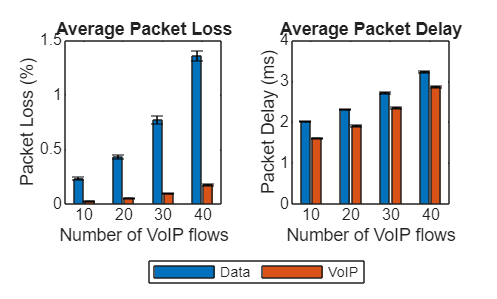

% Performance plots
f_3a = figure;
tiledlayout(1, 2);

nexttile;
PL_mean_3a = [PLdata_mean_3a; PLVoIP_mean_3a];
PL_moe_3a = [PLdata_moe_3a; PLVoIP_moe_3a];
b = bar(n_VoIP, PL_mean_3a, 'grouped');
hold on;
% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(PL_mean_3a);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:ngroups
    x(:,i) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',PL_mean_3a,PL_moe_3a,'k','linestyle','none');
%errorbar(n_VoIP, PLdata_mean_3a, PLdata_moe_3a, '.');
title('Average Packet Loss');
xlabel('Number of VoIP flows');
ylabel('Packet Loss (%)');
hold off;

nexttile;
APD_mean_3a = [APDdata_mean_3a; APDVoIP_mean_3a];
APD_moe_3a = [APDdata_moe_3a; APDVoIP_moe_3a];
b = bar(n_VoIP, APD_mean_3a, 'grouped');
hold on;
% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(PL_mean_3a);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:ngroups
    x(:,i) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',APD_mean_3a,APD_moe_3a,'k','linestyle','none');
%errorbar(n_VoIP, APDdata_mean_3a, APDdata_moe_3a, '.');
title('Average Packet Delay');
xlabel('Number of VoIP flows');
ylabel('Packet Delay (ms)');
hold off;

lgd = legend({'Data', 'VoIP'}, ...
          'Orientation', 'horizontal');
lgd.Layout.Tile = 'south';

saveas(f_3a, fullfile('figures', '3a.svg'));

by observing the results:   

**Average Packet Loss**

- **Trend: **The average packet loss for data packets increases as the number of VoIP flows increases. Similarly, the average packet loss for VoIP packets also increases with the number of VoIP flows yet is considerable smaller to the average packet loss of the data packets.

- **Explanation: **As the number of VoIP flows increases, the competition for the limited queue space intensifies. Starting with $10$ VoIP flows and as the mean time of arrival after the first VoIP packet is $10$ milliseconds, for each flow there arrives a total of $100$ VoIP $\text{pps}$, this in turn makes that after $20$ flows there arrives more VoIP packets than data packets ($1500 \text{ pps}$), the cumulative effect of multiple VoIP flows increases the overall load on the queue making it more probable for any arriving packet to be dropped due to buffer overflow, yet the VoIP packets are less impacted than the data packets due to their smaller average size explaining the discrepancy on the magnitudes of the bars although they have the same priority.

**Average Packet Delay**

- **Trend: **Both the average packet delay for data packets and VoIP packets increases in a similar way as the number of VoIP flows increases, but there exists a discrepancy on the magnitudes being the VoIP lower than the data.

- **Explanation: **Although VoIP packets also experience increased delay with more VoIP flows, the increase is less pronounced compared to data packets due to, once again, their smaller size, this in turn makes them quicker to transmit lowering the average time delay, even when the queue is congested.

**Conclusion**

The addition of VoIP flows impacts both packet loss and delay for data and VoIP packets, yet data packets are more adversely affected due to their larger size, for not being able to fit into a congested queue culminating in an increase in packet loss, and for being slower to transmit culminating in a higher average delay in comparison to the VoIP packets. These results highlight a possible unintended effect of no prioritization where, at some specific states of the system, it may prioritize one packet over the other, in this case prioritizing smaller packets when the queue is near full capacity merely because they fit on the available space.

### 3.b. (Evaluation weight: 10%)

Use `Sim4` to estimate the same performance parameters as in **3.a**. Recall that in `Sim4`, VoIP service has higher priority than data service. Present each of the four performance parameters in a bar chart with the confidence intervals in error bars. Justify the differences in the performance values obtained for each service, and the differences between these results and the results of experiment **3.a**. Draw all relevant  conclusions. 

**Answer:**

% Performance parameters
% data packets
PLdata_3b = zeros(nrun, nsim);
APDdata_3b = zeros(nrun, nsim);
MPDdata_3b = zeros(nrun, nsim);
TT_3b = zeros(nrun, nsim);
% VoIP packets
PLVoIP_3b = zeros(nrun, nsim);
APDVoIP_3b = zeros(nrun, nsim);
MPDVoIP_3b = zeros(nrun, nsim);

for i=1:nsim
    for j=1:nrun
        [PLdata_3b(j,i) , APDdata_3b(j,i) , MPDdata_3b(j,i) , TT_3b(j,i), PLVoIP_3b(j,i), APDVoIP_3b(j,i), MPDVoIP_3b(j,i)] = Sim4(lambda, C, f, P, n_VoIP(i));
    end
end

With the results the confidence intervals can be computed

% data packets
PLdata_mean_3b = zeros(1, nsim);
PLdata_moe_3b = zeros(1, nsim);
APDdata_mean_3b = zeros(1, nsim);
APDdata_moe_3b = zeros(1, nsim);
MPDdata_mean_3b = zeros(1, nsim);
MPDdata_moe_3b = zeros(1, nsim);
TT_mean_3b = zeros(1, nsim);
TT_moe_3b = zeros(1, nsim);
% VoIP packets
PLVoIP_mean_3b = zeros(1, nsim);
PLVoIP_moe_3b = zeros(1, nsim);
APDVoIP_mean_3b = zeros(1, nsim);
APDVoIP_moe_3b = zeros(1, nsim);
MPDVoIP_mean_3b = zeros(1, nsim);
MPDVoIP_moe_3b = zeros(1, nsim);

for i = 1:nsim
    [PLdata_mean_3b(i), PLdata_moe_3b(i)] = CI(PLdata_3b(:, i), "PL", alpha, nrun);
    [APDdata_mean_3b(i), APDdata_moe_3b(i)] = CI(APDdata_3b(:, i), "APD", alpha, nrun);
    [MPDdata_mean_3b(i), MPDdata_moe_3b(i)] = CI(MPDdata_3b(:, i), "MPD", alpha, nrun);
    [TT_mean_3b(i), TT_moe_3b(i)] = CI(TT_3b(:, i), "TT", alpha, nrun);

    [PLVoIP_mean_3b(i), PLVoIP_moe_3b(i)] = CI(PLVoIP_3b(:, i), "PLVoIP", alpha, nrun);
    [APDVoIP_mean_3b(i), APDVoIP_moe_3b(i)] = CI(APDVoIP_3b(:, i), "APDVoIP", alpha, nrun);
    [MPDVoIP_mean_3b(i), MPDVoIP_moe_3b(i)] = CI(MPDVoIP_3b(:, i), "MPDVoIP", alpha, nrun);
end

PL = 2.38e-01 +- 1.21e-02


APD = 2.10e+00 +- 1.21e-02


MPD = 9.46e+00 +- 4.19e-02


TT = 7.90e+00 +- 1.49e-02


PLVoIP = 3.17e-02 +- 6.59e-03


APDVoIP = 4.61e-01 +- 1.15e-03


MPDVoIP = 1.38e+00 +- 5.15e-03


PL = 4.47e-01 +- 2.02e-02


APD = 2.53e+00 +- 1.82e-02


MPD = 1.01e+01 +- 5.06e-02


TT = 8.33e+00 +- 1.39e-02


PLVoIP = 4.86e-02 +- 6.03e-03


APDVoIP = 4.80e-01 +- 1.04e-03


MPDVoIP = 1.44e+00 +- 8.59e-03


PL = 8.13e-01 +- 3.60e-02


APD = 3.12e+00 +- 2.57e-02


MPD = 1.07e+01 +- 5.97e-02


TT = 8.77e+00 +- 1.17e-02


PLVoIP = 9.82e-02 +- 6.16e-03


APDVoIP = 5.02e-01 +- 9.38e-04


MPDVoIP = 1.47e+00 +- 8.14e-03


PL = 1.43e+00 +- 5.43e-02


APD = 3.87e+00 +- 3.96e-02


MPD = 1.13e+01 +- 7.68e-02


TT = 9.15e+00 +- 1.20e-02


PLVoIP = 1.63e-01 +- 9.86e-03


APDVoIP = 5.21e-01 +- 1.17e-03


MPDVoIP = 1.54e+00 +- 1.87e-02


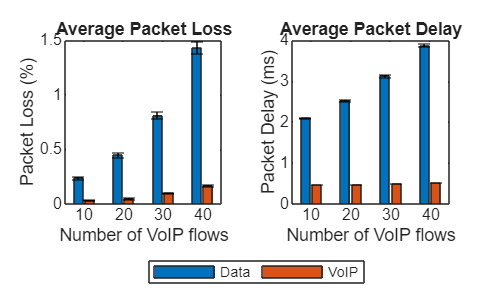

% Performance plots
f_3b = figure;
tiledlayout(1, 2);

nexttile;
PL_mean_3b = [PLdata_mean_3b; PLVoIP_mean_3b];
PL_moe_3b = [PLdata_moe_3b; PLVoIP_moe_3b];
b = bar(n_VoIP, PL_mean_3b, 'grouped');
hold on;
% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(PL_mean_3b);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:ngroups
    x(:,i) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',PL_mean_3b,PL_moe_3b,'k','linestyle','none');
%errorbar(n_VoIP, PLdata_mean_3a, PLdata_moe_3a, '.');
title('Average Packet Loss');
xlabel('Number of VoIP flows');
ylabel('Packet Loss (%)');
hold off;

nexttile;
APD_mean_3b = [APDdata_mean_3b; APDVoIP_mean_3b];
APD_moe_3b = [APDdata_moe_3b; APDVoIP_moe_3b];
b = bar(n_VoIP, APD_mean_3b, 'grouped');
hold on;
% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(PL_mean_3b);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:ngroups
    x(:,i) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',APD_mean_3b,APD_moe_3b,'k','linestyle','none');
%errorbar(n_VoIP, APDdata_mean_3a, APDdata_moe_3a, '.');
title('Average Packet Delay');
xlabel('Number of VoIP flows');
ylabel('Packet Delay (ms)');
hold off;

lgd = legend({'Data', 'VoIP'}, ...
          'Orientation', 'horizontal');
lgd.Layout.Tile = 'south';

saveas(f_3b, fullfile('figures', '3b.svg'))

Plotting both results with and without prioritization

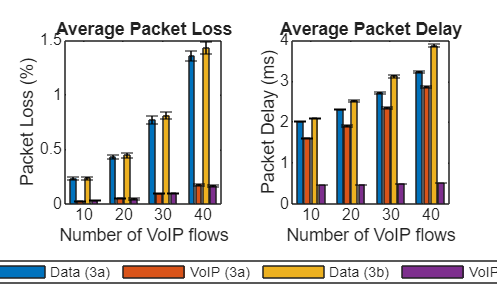

% Comparison plots
fcomparison_3b = figure;
tiledlayout(1, 2);

nexttile;
PL_mean_comparison_3b = [PL_mean_3a; PL_mean_3b];
PL_moe_comparison_3b = [PL_moe_3a; PL_moe_3b];
b = bar(n_VoIP, PL_mean_comparison_3b', 'grouped');
hold on;
% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(PL_mean_comparison_3b);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:ngroups
    x(:,i) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',PL_mean_comparison_3b,PL_moe_comparison_3b,'k','linestyle','none');
%errorbar(n_VoIP, PLdata_mean_3a, PLdata_moe_3a, '.');
title('Average Packet Loss');
xlabel('Number of VoIP flows');
ylabel('Packet Loss (%)');
hold off;

nexttile;
APD_mean_comparison_3b = [APD_mean_3a; APD_mean_3b];
APD_moe_comparison_3b = [APD_moe_3a; APD_moe_3b];
b = bar(n_VoIP, APD_mean_comparison_3b', 'grouped');
hold on;
% Calculate the number of groups and number of bars in each group
[ngroups,nbars] = size(APD_mean_comparison_3b);
% Get the x coordinate of the bars
x = nan(nbars, ngroups);
for i = 1:ngroups
    x(:,i) = b(i).XEndPoints;
end
% Plot the errorbars
errorbar(x',APD_mean_comparison_3b,APD_moe_comparison_3b,'k','linestyle','none');
%errorbar(n_VoIP, APDdata_mean_3a, APDdata_moe_3a, '.');
title('Average Packet Delay');
xlabel('Number of VoIP flows');
ylabel('Packet Delay (ms)');
hold off;

lgd = legend({'Data (3a)', 'VoIP (3a)', 'Data (3b)', 'VoIP (3b)'}, ...
          'Orientation', 'horizontal');
lgd.Layout.Tile = 'south';

saveas(fcomparison_3b, fullfile('figures', '3b_comparison.svg'))

observing the results:

**Average Packet Loss**

- **Trend: **Both the average packet loss for data and VoIP packets with and without prioritization increase with the number of flows, being in both cases of prioritization the VoIP having a considerably less average packet loss in comparison to its data packet counterpart.

- **Explanation: **The addition of VoIP priority does not change the packet loss for any of the types of packets, this is due to the loss being attributed to the queue overflow, as mentioned on the previous answer, due to the system already prioritizing, inadvertently, the smaller packets, the addition of a VoIP priority does not change the results.

**Average Packet Delay**

**Trend: **The average packet delay for both data and VoIP packets increases with the number of VoIP flows yet the addition of VoIP priority decreases considerably the average delay for the VoIP packets and increases slightly the average data packet delay.

**Explanation: **Without prioritization, both data and VoIP packets experience increased delays as the queue becomes more congested. Data packets, being larger, take longer to transmit, resulting in higher delays compared to VoIP packets. By prioritizing VoIP packets ensures they are transmitted quickly, maintaining a low average delay. Data packets, however, experience longer delays as they must wait for the VoIP packets to be transmitted first, especially as the number of VoIP flows increases.

**Conclusion**

Prioritizing VoIP packets significantly improves their performance but at the cost of a slightly longer delay for data packets, the packet loss remains with no significant changes as the packet can only be dropped due to queue overflow and as written in the previous answer, the queue already prioritizes VoIP packets due to their smaller size.

### 3.c. (Evaluation weight: 5%)

Develop a new version of `Sim4`, named `Sim4A`, to estimate the  same performance parameters as `Sim4` changing the queue packet discard algorithm as follows: arriving VoIP packets are always accepted in the queue (if there is enough space)  but arriving data packets are accepted in the queue only if the total queue occupation does  not become higher than $p$ (in $\%$) of the queue size (parameter $p$ should be a new input  parameter of `Sim4A`). Present the developed MATLAB function of `Sim4A` highlighting  and justifying the introduced changes. 

**Answer:**

### 3.d. (Evaluation weight: 5%)

Use simulator `Sim4A` to estimate the same performance  parameters as in **3.a** and **3.b** for $p = 90 \%$. Justify the differences in the performance values  obtained for each service, and the differences between these results and the results of  experiment **3.b**. Draw all relevant conclusions. 

**Answer:**

### 3.e. (Evaluation weight: 5%)

Repeat experiment **3.d** considering now $p = 60 \%$. Justify the  differences in the performance values obtained for each service, and the differences  between these results and the results of experiments **3.b** and **3.d**. Draw all relevant conclusions.

**Answer:**

## References:

[3]: